#  建模大脑神经元

该研究将对大脑中所携带的信号进行建模。

[神经元](https://www.youtube.com/watch?v=HZh0A-lWSmY)是一种可电激发的细胞，它通过电信号和化学信号接收、处理和传递信息。 神经元之间的通讯是通过控制调节[膜电位](https://www.youtube.com/watch?v=tIzF2tWy6KI)的离子通道来建立的。在施加相当幅度的电流脉冲后，可兴奋细胞的膜电位在返回平衡状态之前显示出很大的变化，称为动作电位 (*Action Potential, *AP)。

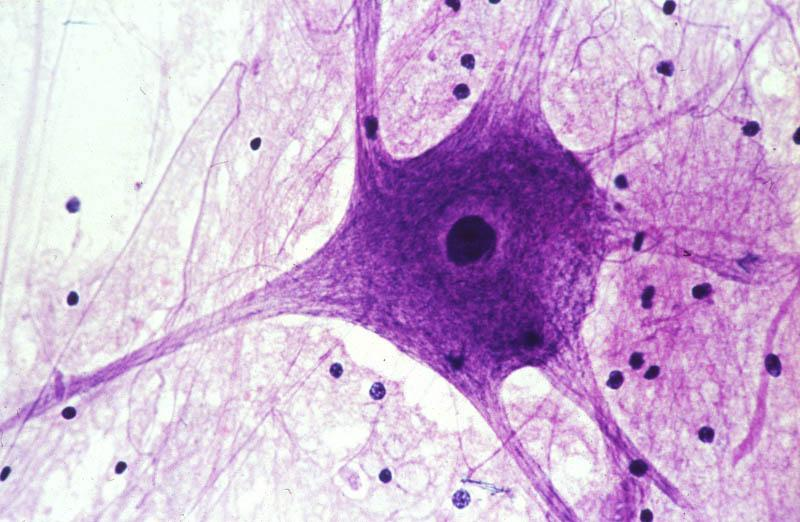

描述神经元动作电位最著名的[模型](https://zhuanlan.zhihu.com/p/102770891)是 [霍奇金–赫胥黎模型](https://www.ncbi.nlm.nih.gov/pmc/articles/PMC1392413/)。

## 霍奇金–赫胥黎模型

膜电位 (V) 的值由几个离子（钠、钾和其他离子）透过膜的离子通道进行流动来定义。

*The Hodgin-Huxley model* provide the resolution of a system of four ordinary differential equations. The first equation represent the total current through the membrane (Eq 1.1), to which are added three state equations. Indeed m, h and n are state variables that describe the kinetics of the different ion channels and their value is defined by a specific differential equation (see Appendix section).

$C\frac{dV}{dt}+g_{Namax}m^{3}h\left(V-E_{Na}\right)+g_{Kmax}n^{4}\left(V-E_{K}\right)+g_{eq}\left(V-E_{eq}\right)=i$              (Eq 1.1)

In order to solve the differential system we can use the [Euler's method](https://www.youtube.com/watch?time_continue=274&v=q87L9R9v274), a 1st order numerical method useful to find the solution of the system with a given initial value for each equation (see Local Functions section for the detailed function that includes this method to solve the system). For this reason, in order to simulate the behaviour of the neuron, we have to set all the initial values. Initially we can assume that the neuron is in equilibrium, without any external stimolous applied ($I=0$). Regarding the initial value of V ($V_{0}=V\left(t=0\right)$), we can set this to a typical resting potential of -65 mV, while for m, n and h we have to think a little bit...

V0 = -65; % Resting Potential [mV]

**What are the initial values of m, n and h that ensure a condition of equilibrium in the neuron in absence of the external current I?**

We can take a look on the ordinary differential equations system and solve it under the assumption of $I=0$ and the equilibrium condition, reached when all the derivatives are 0: $\frac{dV}{dt}$= 0, $\frac{dm}{dt}=0$, $\frac{dn}{dt}=0$ and $\frac{dh}{dt}=0
$. The last 3 conditions leads to 3 algebraic equations that allows to obtain the target initial values. In particular, for $m$ (and similarly for $n$ and $h$):

$0=\alpha_{m}\left(V_{0}\right)\left(1-m_{0}\right)-\beta_{m}\left(V_{0}\right)m_{0}$,

where $m_{0}=m\left(t=0\right)$.

Solving the algebraic equation in $m_{0}$ evaluating $\alpha_{m}\left(V_{0}\right)$ and $\beta_{m}\left(V_{0}\right)$ (see Appendix section) we get the initial value of $m$ (and similarly for $n$ and $h$).

alpha_m0 = 0.1*(-40-V0)/( exp( (-40 - V0) /10 ) - 1 );
beta_m0 = 4*exp( (-V0 - 65)/18 );
m0 = alpha_m0 / (alpha_m0 + beta_m0);

alpha_n0 = 0.01*(-55-V0)/( exp( (-55 - V0) /10 ) - 1 );
beta_n0 = 0.125*exp( (-V0 - 65)/80 );
n0 = alpha_n0 / (alpha_n0 + beta_n0);

alpha_h0 = 0.07*exp( (-V0 - 65)/20 );
beta_h0 = 1/( exp( (-V0 - 35)/10 ) + 1);
h0 = alpha_h0 / (alpha_h0 + beta_h0);

initial_values=[V0, m0, n0, h0];
enable_Na=1;% Normal Na dynamics (flag enable_Na=1)
enable_K=1;% Normal K dynamics (flag enable_K=1)

During all next simulations we have to define a time vector based on the maximum time value of simulation ($t_{max}$) and the time step value ($\Delta t$), with the last one particularly important for the Euler's method. Let's set $t_{max}=100\ ms$ and $\Delta t=0.01\ ms$.

dt = 0.01; % Temporal resolution or time step [ms]
tmax = 100;  % Maximum time of simulation [ms]
t = 0:dt:tmax; % Time vector [ms]
L = length(t); % Number of samples

**What happens at the neuron without any external stimulus (**$\mathbf{I=0\ nA}$)**?**

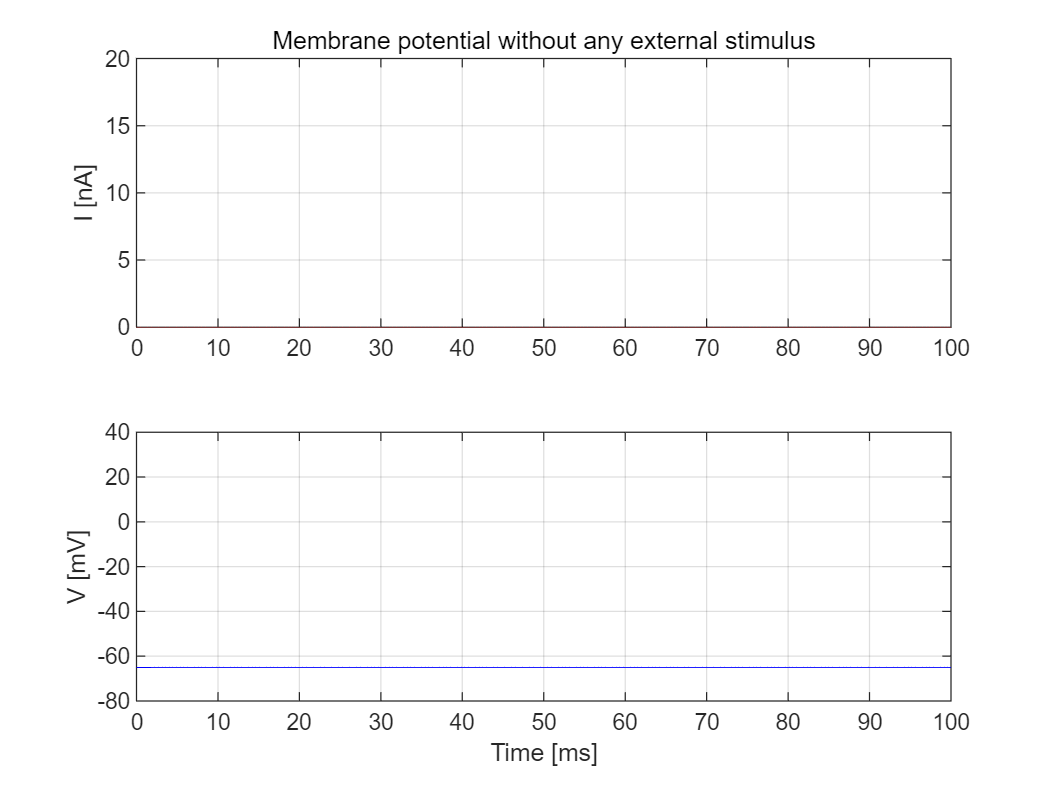

I = zeros(L,1); % External stimulus vector [nA]
V=solve_model_HH(initial_values, I, dt, enable_Na, enable_K); % Membrane potential [mV] obtained by solving the model with I

figure()
subplot(2,1,1),plot(t,I,'red'),grid on,box on,axis([0,100,0,20]),ylabel('I [nA]')
title('Membrane potential without any external stimulus')
subplot(2,1,2),plot(t,V,'blue'),grid on,box on,axis([0,100,-80,40]),xlabel('Time [ms]'),ylabel('V [mV]')

As we can see from the previous figure, with an external current value $I=0\ nA$ the membrane potential remains constant at the resting value.

Now, let's suppose that an external stimulus reaches the neuron (i.e. thermoception or auditory perception). This stimulus can be modeled as a current and, based on its intensity our brain can perceive it: if the intensity is enough to trigger an AP in the neuron the information goes on.

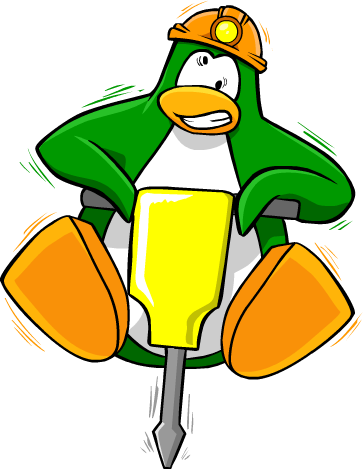                         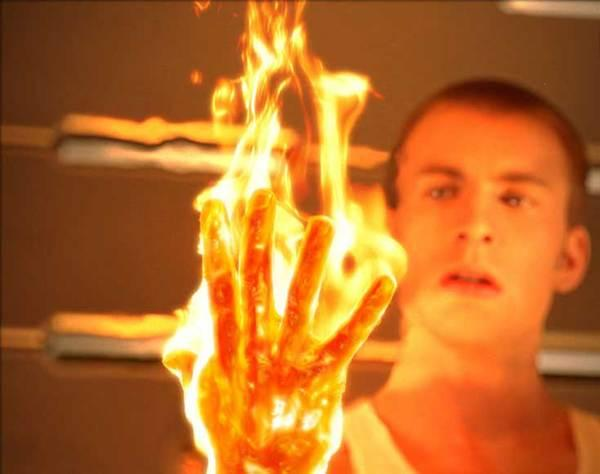

In the following, two main case of studies are reported: in the first one an external *constant stimulus* is applied to the neuron, while in the second one an external *impulsive stimulus* is applied.

## **Part I: Application of an external constant **stimulus

**How changes the AP of a neuron with an increasing external constant current?**

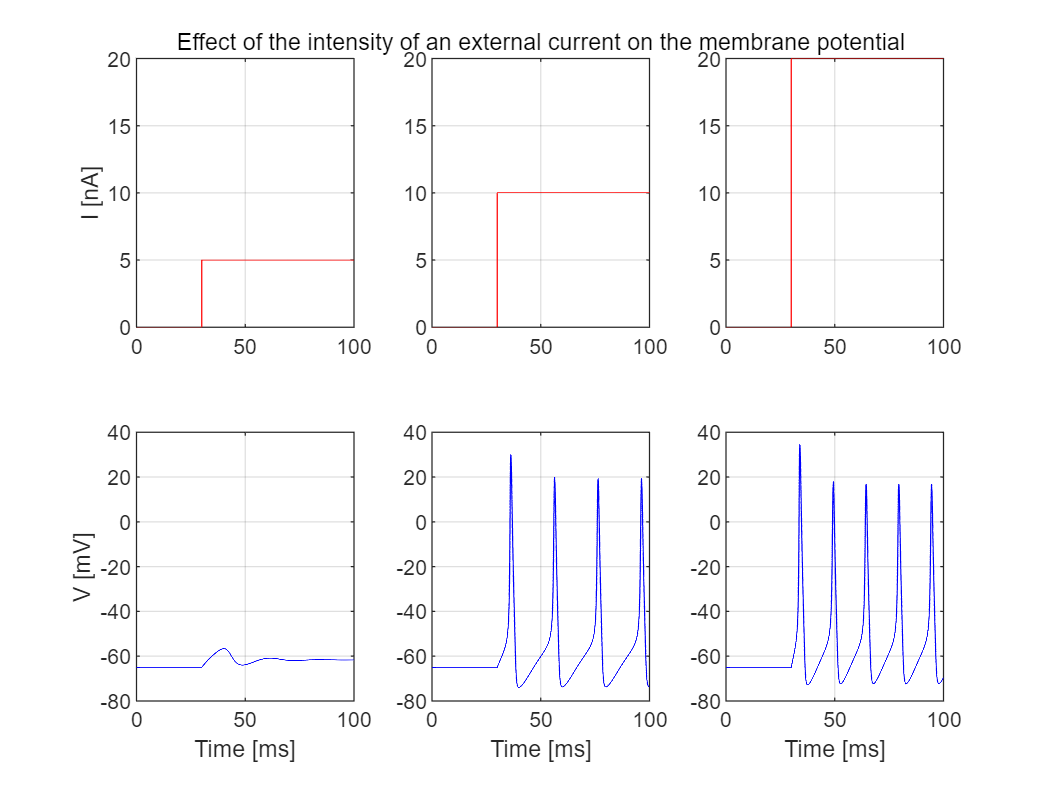

tI = 30; % Time of application of an external constant stimulus [ms]
I1 = [zeros(floor(tI/dt),1);5*ones(L-floor(tI/dt),1)]; % External stimulus vector of 5 nA applied at tI
I2 = [zeros(floor(tI/dt),1);10*ones(L-floor(tI/dt),1)]; % External stimulus vector of 10 nA applied at tI
I3 = [zeros(floor(tI/dt),1);20*ones(L-floor(tI/dt),1)]; % External stimulus vector of 20 nA applied at tI
V1=solve_model_HH(initial_values, I1, dt, enable_Na, enable_K); % Membrane potential [mV] obtained by solving the model with I1
V2=solve_model_HH(initial_values, I2, dt, enable_Na, enable_K); % Membrane potential [mV] obtained by solving the model with I2
V3=solve_model_HH(initial_values, I3, dt, enable_Na, enable_K); % Membrane potential [mV] obtained by solving the model with I3

figure()
subplot(2,3,1),plot(t,I1,'red'),grid on,box on,axis([0,100,0,20]),ylabel('I [nA]')
subplot(2,3,4),plot(t,V1,'blue'),grid on,box on,axis([0,100,-80,40]),xlabel('Time [ms]'),ylabel('V [mV]')
subplot(2,3,2),plot(t,I2,'red'),grid on,box on,axis([0,100,0,20])
title('Effect of the intensity of an external current on the membrane potential')
subplot(2,3,5),plot(t,V2,'blue'),grid on,box on,axis([0,100,-80,40]),xlabel('Time [ms]')
subplot(2,3,3),plot(t,I3,'red'),grid on,box on,axis([0,100,0,20])
subplot(2,3,6),plot(t,V3,'blue'),grid on,box on,axis([0,100,-80,40]),xlabel('Time [ms]')

As we can see from the previous figure, with an external current value $I=5\ nA$ the membrane potential shows an initial transient and for $t\rightarrow \inf$ it settles on a value near to the resting value. Instead, with an external current value $I=10\ nA$ or $I=15\ nA$ the neuron produce many APs (second and third column of plots). A single AP is composed by an initial depolarization phase, in which the potential grows up, and a repolarization phase, in which the potential falls down, in both cases mantaining $V>V_{0}$. After that, there is a hyperpolarization phase where the potential reaches values $V<V_{0}$. Furthermore, we can notice the *stereotyped behaviour of the AP*: regardless the amplitude of the current applied, a single AP pattern occurs in the same way once the potential exceeds the *threshold potential *(all-or-none law). For this reason, when an external stimulus is big enough to reach our brain, a *train of APs *is generated and the information is encoded in frequency (second and third columns).

**What is the relationship between discharge frequency and current amplitude?**

The discharge frequency of the AP depends on the intensity of the depolarizing continuous current. Although the discharge rate increases with an increasing current exists a limit to the frequency with which a neuron is able to generate APs. The maximum discharge frequency is around 1000 Hz and once an AP has started it's not possible to generate another for at least 1 msec. 

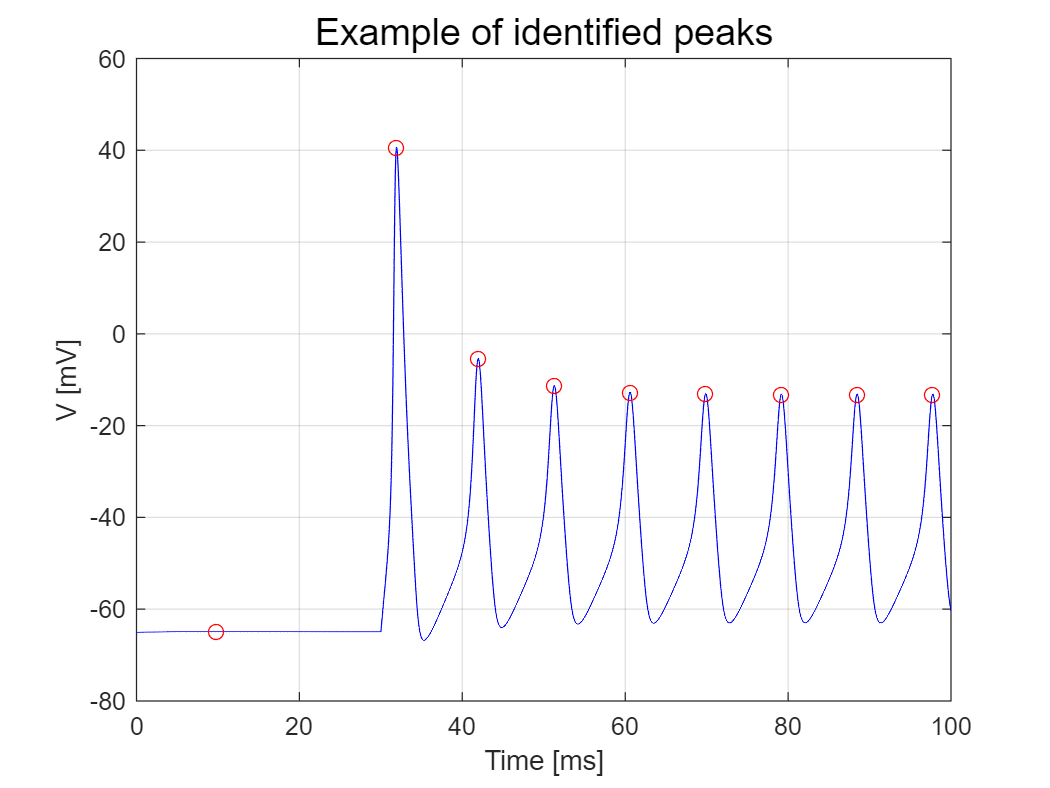

start_current=10; % Start current value to investigate [nA]
end_current=80; % Stop current value to investigate [nA]
current = start_current:5:end_current; % Current values to investigate [nA]
frequency = zeros(size(current)); % Frequency vector preallocation [Hz]
for i=1:length(current)
    I = [zeros(floor(tI/dt),1);current(i)*ones(L-floor(tI/dt),1)]; % External stimulus vector considering the i-th current value applied at tI
    V=solve_model_HH(initial_values, I, dt, enable_Na, enable_K); % Membrane potential [mV] obtained by solving the model with the i-th current I
    [peaks,locs]=findpeaks(V); % Evaluation of peaks in the membrane potential signal
    time_between_peaks=t(locs(5:end))-t(locs(4:end-1)); % To avoid the initial irregular APs, the time interval is evaluated considering the last two peaks
    frequency(i)=1000*mean(1./time_between_peaks); % Frequency obtained with the i-th current [Hz]
end

figure()
plot(t,V,'b'),grid on,box on,title('Example of identified peaks','FontSize',15)
hold on,plot(t(locs),peaks,'ro'),xlabel('Time [ms]'),ylabel('V [mV]')

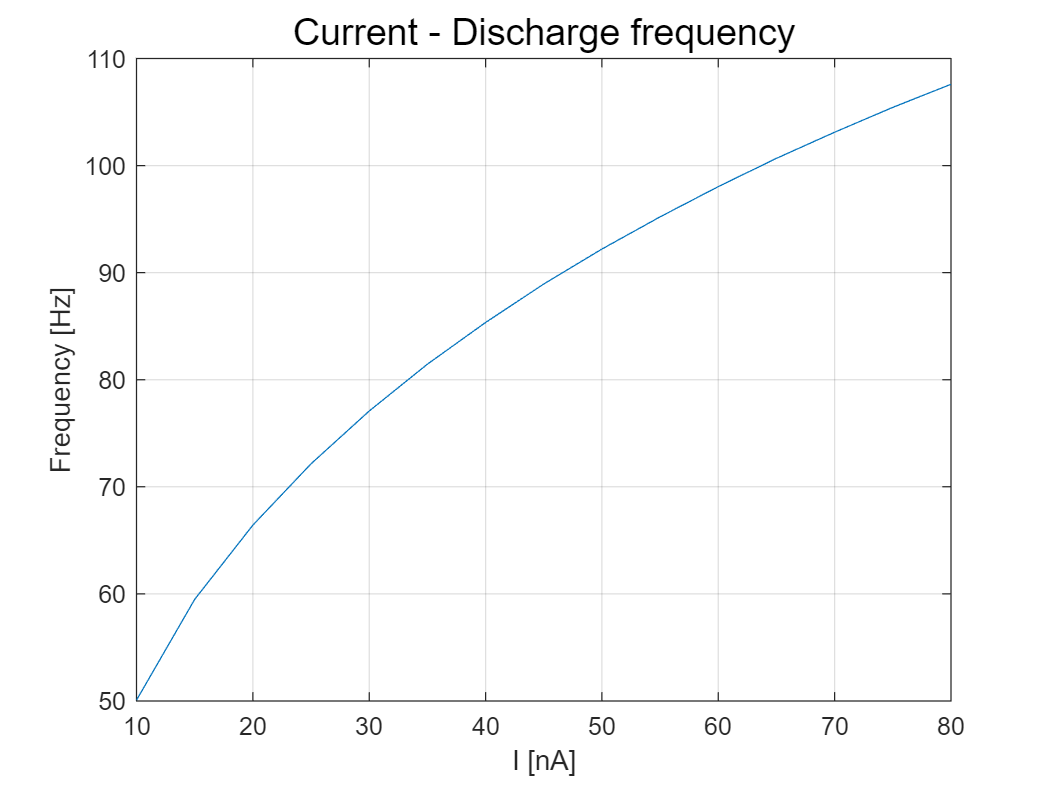

figure()
plot(current,frequency),grid on,box on, 
xlabel('I [nA]'), ylabel('Frequency [Hz]'), title('Current - Discharge frequency','FontSize',15)

**What happens if we have a neural pathology that involves sodium channelopathy?**

Now let's suppose that our neuron is affected by a disease that involves sodium channels and in particular their dynamics. How do you think this will affect the shape of the AP?

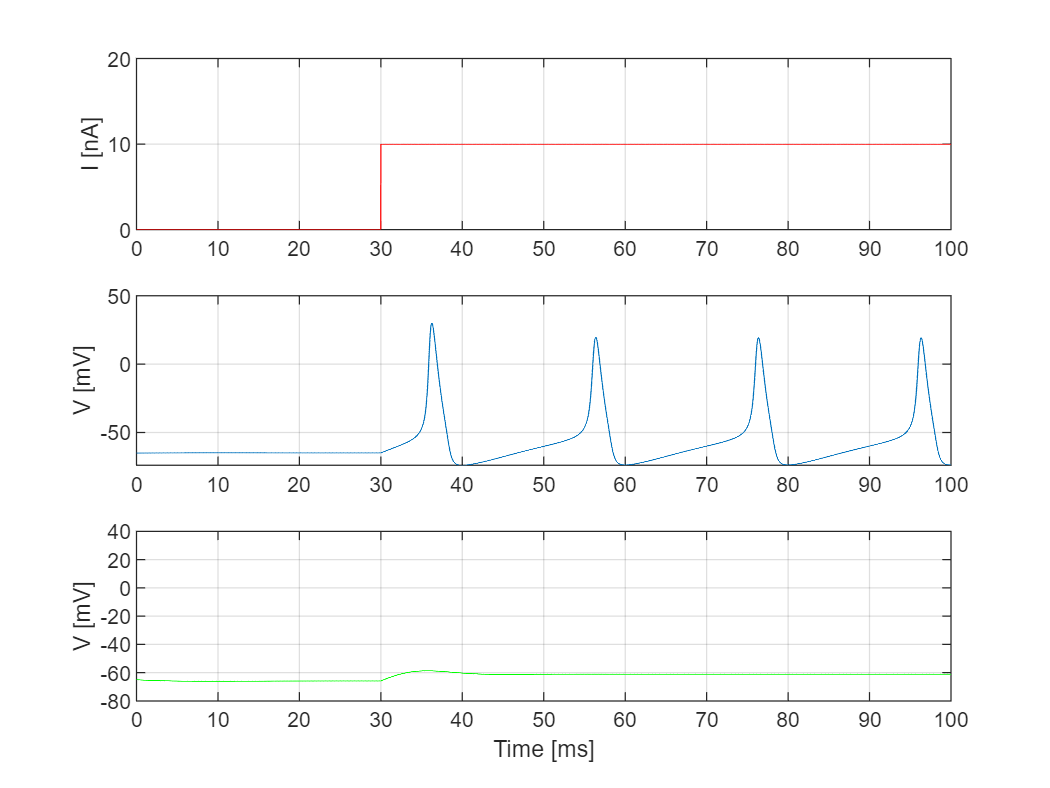

I=[zeros(floor(tI/dt),1);10*ones(L-floor(tI/dt),1)]; % External stimulus vector of 10 nA applied at tI

% Case Normal Action Potential
enable_Na=1; % Normal Na dynamics (flag enable_Na=1)
enable_K=1; % Normal K dynamics (flag enable_K=1)
V_normal=solve_model_HH(initial_values, I, dt, enable_Na, enable_K); % Membrane potential [mV] obtained by solving the model with I and normal flags

% Case Sodium Channelopathy
enable_Na=0; % Pathological Na dynamics (flag enable_Na=0)
enable_K=1; % Normal K dynamics (flag enable_K=1)
V_noNa=solve_model_HH(initial_values, I, dt, enable_Na, enable_K); % Membrane potential [mV] obtained by solving the model with I and pathological Na flag

figure()
subplot(3,1,1),plot(t,I,'r'), grid on, box on, ylabel('I [nA]'), axis([0,100,0,20])
subplot(3,1,2),plot(t,V_normal),grid on, box on,ylabel('V [mV]'), 
subplot(3,1,3),plot(t,V_noNa,'g'),grid on, box on, xlabel('Time [ms]'),ylabel('V [mV]'), axis([0,100,-80,40])

From the previous figure we can understand the *Na-channels role* evaluating the first deporalization phase of the AP: with an impairment of 100% the membrane potential can't reach the threshold in order to trigger an AP. You can try to change enable_Na value between 0 and 1 to see intermediate behaviours.

## **Part II: Application of an impulsive constant stimulus**

In order to simulate in a better way the biological behaviour of a neuron, we could apply an impulsive constant stimulus.

**What happens to the membrane potential if we apply a sequence of two stimuli by varying the temporal distance between them?**

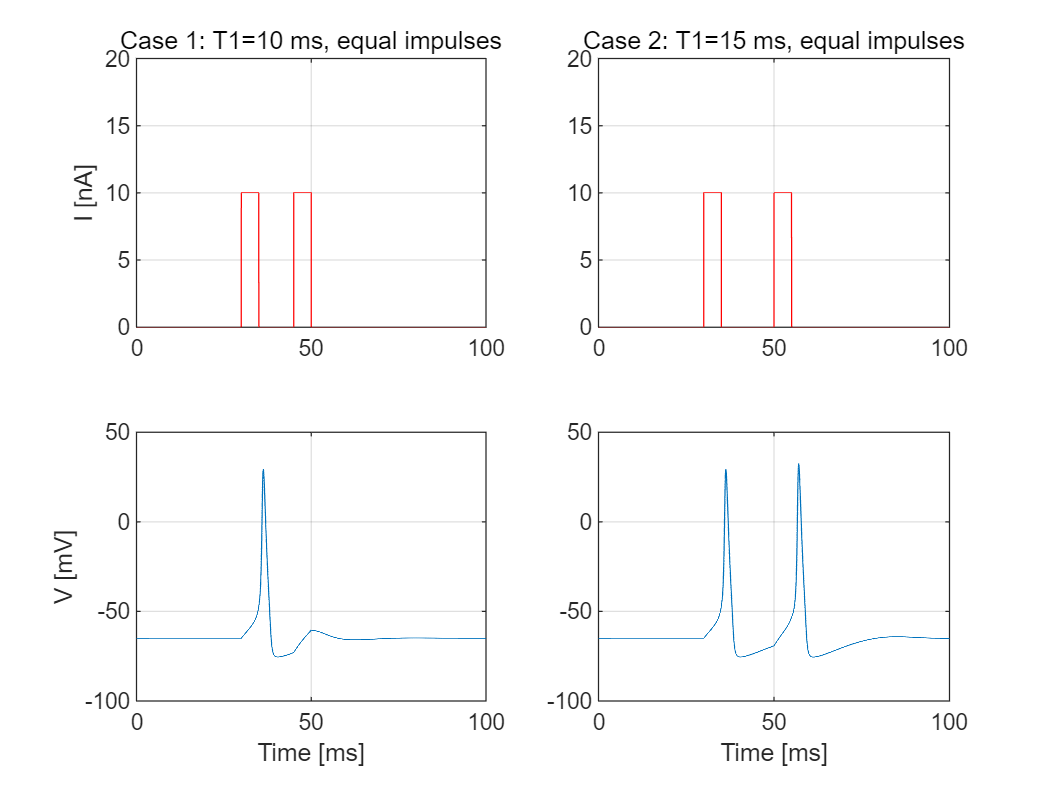

I0=10; % [nA]
deltaI=500;
enable_Na=1; % Normal Na dynamics (flag enable_Na=1)
enable_K=1; % Normal K dynamics (flag enable_K=1)
% Case 1: temporal distance between impulses of 10 ms
T1=10; % [ms]
I1=zeros(L,1);
I1(floor(tI/dt):floor(tI/dt)+deltaI)=I0;
I1(floor(tI/dt)+deltaI+1+floor(T1/dt):floor(tI/dt)+2*deltaI+1+floor(T1/dt))=I0; % External impulsive stimulus vector I1
V1=solve_model_HH(initial_values, I1, dt, enable_Na, enable_K); % Membrane potential [mV] obtained by solving the model with I1
% Case 2: temporal distance between impulses of 15 ms
T2=15; % [ms]
I2=zeros(L,1);
I2(floor(tI/dt):floor(tI/dt)+deltaI)=I0;
I2(floor(tI/dt)+deltaI+1+floor(T2/dt):floor(tI/dt)+2*deltaI+1+floor(T2/dt))=I0; % External impulsive stimulus vector I2
V2=solve_model_HH(initial_values, I2, dt, enable_Na, enable_K); % Membrane potential [mV] obtained by solving the model with I2

figure()
subplot(2,2,1),plot(t,I1,'r'), grid on, box on,ylabel('I [nA]'), axis([0,100,0,20])
title('Case 1: T1=10 ms, equal impulses')
subplot(2,2,3),plot(t,V1),grid on, box on,xlabel('Time [ms]'),ylabel('V [mV]')
subplot(2,2,2),plot(t,I2,'r'), grid on, box on, axis([0,100,0,20])
title('Case 2: T1=15 ms, equal impulses')
subplot(2,2,4),plot(t,V2),grid on, box on,xlabel('Time [ms]'), 

As we can see from the previous figure, with a temporal distance of 10 ms the last impulse doesn't trigger the AP due to the *refractory period*. This is split up in *absolute* and *relative.* During the first one is absolutely impossible the AP genesis, regardless the amplitude of the 2nd current impulse. Instead, during the last one, is possible the AP genesis with a higher current amplitude of the 2nd current impulse. Now, let's try to see if in the first case (temporal distance of 10 ms) we can have a 2nd AP with a higher current amplitude, and then if we are or not in the relative refractory period.

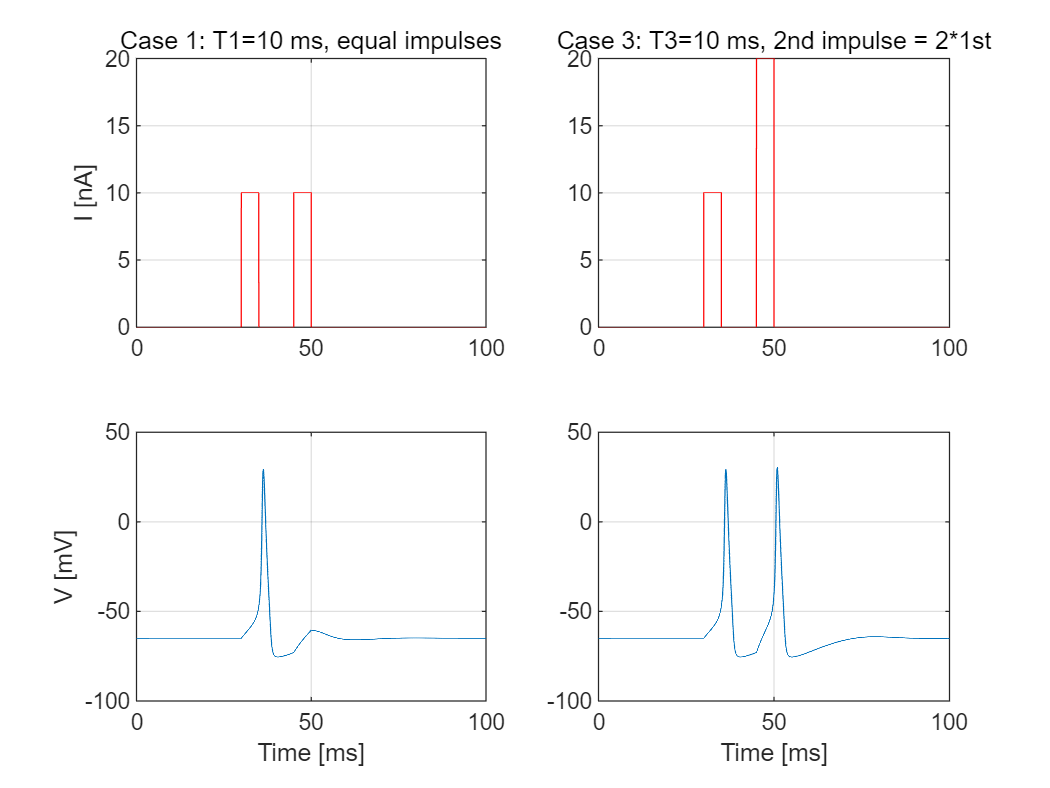

% Case 3: temporal distance between impulses of 10 ms, higher amplitude of the 2nd impulse
T3=T1; % [ms]
I3=zeros(L,1);
I3(floor(tI/dt):floor(tI/dt)+deltaI)=I0;
I3(floor(tI/dt)+deltaI+1+floor(T3/dt):floor(tI/dt)+2*deltaI+1+floor(T3/dt))=2*I0; % External impulsive stimulus vector I3
V3=solve_model_HH(initial_values, I3, dt, enable_Na, enable_K); % Membrane potential [mV] obtained by solving the model with I3

figure()
subplot(2,2,1),plot(t,I1,'r'), grid on, box on,ylabel('I [nA]'), axis([0,100,0,20])
title('Case 1: T1=10 ms, equal impulses')
subplot(2,2,3),plot(t,V1),grid on, box on,xlabel('Time [ms]'),ylabel('V [mV]')
subplot(2,2,2),plot(t,I3,'r'), grid on, box on, axis([0,100,0,20]),
title('Case 3: T3=10 ms, 2nd impulse = 2*1st')
subplot(2,2,4),plot(t,V3),grid on, box on,xlabel('Time [ms]'),

Great! So we were in the relative refractory period.

You can try to decrease the delay T3 until you reach the absolute refractory period when the 2nd AP disappear (i.e. try with T3=2 ms).

In this trip inside the brain we deepened some neurophysiological aspects of the communication between neurons with the first but powerful system developed for the modeling of the neuron activity. We hope that you enjoyed this Live Editor experience!

## Appendix

*Additional Status Variables:* m, h, n describes the kinetics of ion channels, with values between 0 and 1. They are associated with sodium channel activation, sodium channel inactivation and potassium channel activation, respectively. For more details see the original work of [Hodgkin-Huxley](https://www.ncbi.nlm.nih.gov/pmc/articles/PMC1392413).

- 
$$\frac{dm}{dt}=\alpha_{m}\left(V\right)\left(1-m\right)-\beta_{m}\left(V\right)m$$


- 
$$\frac{dh}{dt}=\alpha_{h}\left(V\right)\left(1-h\right)-\beta_{h}\left(V\right)h
$$


- 
$$\frac{dn}{dt}=\alpha_{n}\left(V\right)\left(1-n\right)-\beta_{n}\left(V\right)n$$


*Additional Boltzmann Equations*: $\alpha$ and $\beta
$ are obtained from the following algebraic equations, based on Hodgin-Huxley sperimental results.

- 
$$\alpha_{m}\left(V\right)=0.1\frac{-40-V}{\exp{\left(\frac{-40-V}{10}\right)}-1}$$


- 
$$\beta_{m}\left(V\right)=4\exp{\left(\frac{-65-V}{-18}\right)}
$$


- 
$$ \alpha_{h}\left(V\right)=0.07\exp{\left(\frac{-65-V}{-20}\right)}$$


- 
$$\beta_{h}\left(V\right)=\frac{1}{\exp{\left(\frac{-35-V}{10}\right)+1}}$$


- 
$$\alpha_{n}\left(V\right)=0.01\frac{-55-V}{\exp{\left(\frac{-55-V}{10}\right)}-1}$$


- 
$$\beta_{n}\left(V\right)=0.125\exp{\left(\frac{-65-V}{80}\right)}$$


## Local Functions

function V=solve_model_HH(initial_values, I, dt, enable_Na, enable_K)
    % Setting some parameters of the model (1), (2), (3)
    % (1) Electrical Conductances of Sodium (Na), Potassium (K) and Equivalent Ions (Eq) 
    gNamax = 120; gKmax = 36;  gEq = 0.3;  
    % (2) Voltage Sources due to electrochemical gradients of Sodium (Na), Potassium (K) and Equivalent Ions (Eq) in [mV]
    ENa = 55; EK = -77; EEq = -54.4;
    % (3) Capacity of the membrane 
    C = 4;
    L=length(I);
    % Preallocation of V, m, n and h
    V = zeros(1,L); 
    m = zeros(1,L);
    n = zeros(1,L);
    h = zeros(1,L);
    % Setting initial values of V, m, n and h
    V(1) = initial_values(1);
    m(1) = initial_values(2);
    n(1) = initial_values(3);
    h(1) = initial_values(4);
    % Definition of the initial values of alpha_m, beta_m, alpha_n, beta_n, alpha_h and beta_h, useful for finding the solution
    alpha_m = 0.1*(-40-V(1))/( exp( (-40 - V(1)) /10 ) - 1 );
    beta_m = 4*exp( (-V(1) - 65)/18 );
    alpha_h = 0.07*exp( (-V(1) - 65)/20 );
    beta_h = 1/( exp( (-V(1) - 35)/10 ) + 1);
    alpha_n = 0.01*(-55-V(1))/( exp( (-55 - V(1)) /10 ) - 1 );
    beta_n = 0.125*exp( (-V(1) - 65)/80 );

    for i = 1: L-1
        % Euler's method applied to the ordinary differential equations system
        dV = 1/C * ( -gKmax*n(i)^4*(V(i) - EK)*enable_K - gNamax*m(i)^3*h(i)*(V(i) -ENa)*enable_Na - gEq*(V(i) - EEq) + I(i));
        dm = alpha_m*(1 - m(i)) - beta_m*m(i);
        dn = alpha_n*(1 - n(i)) - beta_n*n(i);
        dh = alpha_h*(1 - h(i)) - beta_h*h(i);
    
        V(i+1) = V(i) + dV*dt;
        m(i+1) = m(i) + dm*dt;
        n(i+1) = n(i) + dn*dt;
        h(i+1) = h(i) + dh*dt;
        
        % Update of alpha_m, beta_m, alpha_n, beta_n, alpha_h and beta_h, useful for finding the solution at the next step
        alpha_m = 0.1*(-40-V(i+1))/( exp( (-40 - V(i+1)) /10 ) - 1 );
        beta_m = 4*exp( (-V(i+1) - 65)/18 );
        alpha_h = 0.07*exp( (-V(i+1) - 65)/20 );
        beta_h = 1/( exp( (-V(i+1) - 35)/10 ) + 1);
        alpha_n = 0.01*(-55-V(i+1))/( exp( (-55 - V(i+1)) /10 ) - 1 );
        beta_n = 0.125*exp( (-V(i+1) - 65)/80 );
    end
end